# Computer Vision Lab 5 - Exercise 1

**Authors**: Emer Rodriguez Formisano and Jorge Alexander

**Date**: 20/11/2017

## 1. Introduction

%% Initialization
% Define Viola & Jones parameters for the first two feature masks
% Following the figure 1 for details!!
L = 80;                            % mask size [px]
d1 = 10; d2 = 15; d3 = 15; d4 = 10; % distances from the border
w1 = 50; w2 = 20; w3 = 20;          % width of the rectangles
h1 = 10; h2 = 20;                   % height of the rectangles

%% Load image, compute Integral Image and visualize it

% Load image 'NASA1.jpg' and convert image from rgb to grayscale 
nasa1Rgb = imread('NASA1.bmp');
%imshow(nasa1Rgb)

I = rgb2gray(nasa1Rgb);
%imshow(I)

% Compute the Integral Image
% >> code to compute the integral image S <<
S = cumsum(cumsum(double(I),2));
%imshow(S, []);  % Rescale 


## 2. Integral Images and Haar-like 

2.1.1 Compute and visualize Haar-like features


% (X,Y) coordinates of the top-left corner of windows with face
X = [193 340 444 573 717 834 979 1066 1224 195 445 717 964 1200];
Y = [118 151 112 177 114 177 121 184 127 270 298 279 285 295];
XY_FACE =  [X' Y'];    %[x1 y1; x2 y2 .....]

% Initialize the feature matrix for faces
FEAT_FACE = [];

for i = 1:size(XY_FACE,1)
    
    % current top-left corner coordinates
     x = XY_FACE(i,1); 
     y = XY_FACE(i,2);
    
    % compute area of regions A and B for the first feature
    % HERE WE USE INTEGRAL IMAGE!
    area_A = S(y+d1+h1,x+d2+w1) - S(y+d1+1,x+d2+w1) - (S(y+d1+h1,x+d2+1) - S(y+d1+1,x+d2+1));
    area_B = S(y+2*h1+d1,x+w1+d2) - S(y+d1+h1+1,x+d2+w1) - (S(y+d1+2*h1,x+d2+1)-S(y+d1+h1+1,x+d2+1));
    
    % compute area of regions C, D and E for the second feature
    % HERE WE USE INTEGRAL IMAGE!
    % >> code to compute the area of regions C and E <<
    area_C = S(y+d3+h2,x+d4+w2) -       S(y+d3+h2,x+d4) -       S(y+d3,x+d4+w2) +       S(y+d3,x+d4);
    area_D = S(y+d3+h2,x+d4+w2+w3) -    S(y+d3+h2,x+d4+w2) -    S(y+d3,x+d4+w2+w3) +    S(y+d3,x+d4+w2); 
    area_E = S(y+d3+h2,x+d4+w2+w3+w2) - S(y+d3+h2,x+d4+w2+w3) - S(y+d3,x+d4+w2+w3+w2) + S(y+d3,x+d4+w2+w3);
    
    
    % compute features value
    F1 = area_B - area_A;
    F2 = area_D - (area_C + area_E);
    
    % cumulate the computed values
    FEAT_FACE = [FEAT_FACE; [F1 F2]];
    
end

%% Compute features for regions with non-faces

% (X,Y) coordinates of the top-left corner of windows with non-face
X=[ 28 307 574 829 1093 203 350 523 580 800 931 1127 692 1265];
Y=[ 36    28    27    30    46   768   757   742   859   745   912   777   994   820];
XY_NON_FACE = [X' Y'];

% Initialize the feature matrix for non-faces
FEAT_NON_FACE = [];

for i = 1:size(XY_NON_FACE,1)
    
    % current top-left corner coordinates
    x = XY_NON_FACE(i,1); y = XY_NON_FACE(i,2);
    
    % compute area of regions A and B for the first feature
    % HERE WE USE INTEGRAL IMAGE!
    area_A = S(y+d1+h1,x+d2+w1) - S(y+d1+1,x+d2+w1) - (S(y+d1+h1,x+d2+1) - S(y+d1+1,x+d2+1));
    area_B = S(y+2*h1+d1,x+w1+d2) - S(y+d1+h1+1,x+d2+w1) - (S(y+d1+2*h1,x+d2+1)-S(y+d1+h1+1,x+d2+1));
    
    % compute area of regions C, D and E for the second feature
    % HERE WE USE INTEGRAL IMAGE!
    % >> code to compute the area of regions C and E <<
    area_C = S(y+d3+h2,x+d4+w2) -       S(y+d3+h2,x+d4) -       S(y+d3,x+d4+w2) +       S(y+d3,x+d4);
    area_D = S(y+d3+h2,x+d4+w2+w3) -    S(y+d3+h2,x+d4+w2) -    S(y+d3,x+d4+w2+w3) +    S(y+d3,x+d4+w2); 
    area_E = S(y+d3+h2,x+d4+w2+w3+w2) - S(y+d3+h2,x+d4+w2+w3) - S(y+d3,x+d4+w2+w3+w2) + S(y+d3,x+d4+w2+w3);

    % compute features value
    F1 = area_B - area_A;
    F2 = area_D - (area_C + area_E);
    
    % cumulate the computed values
    FEAT_NON_FACE = [FEAT_NON_FACE; [F1 F2]];
    
end

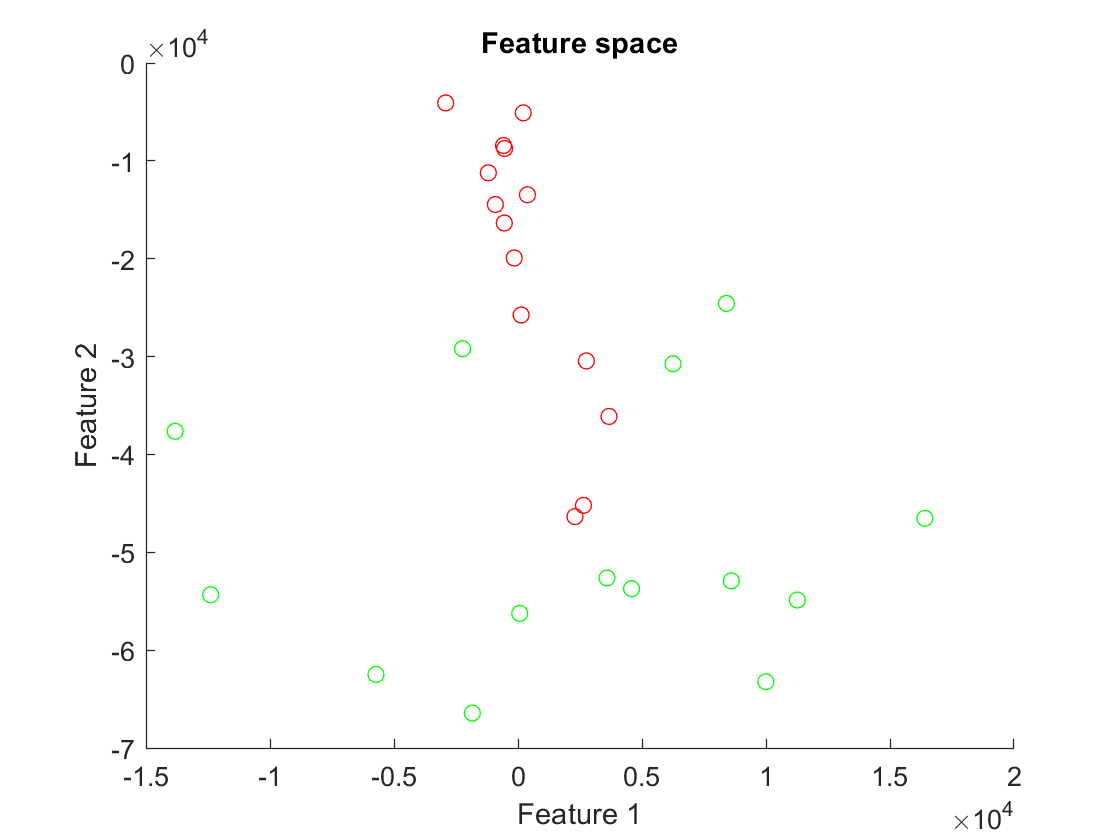

%% Visualize samples in the feature space
figure(3)
hold on
scatter(FEAT_FACE(:,1),FEAT_FACE(:,2),'g');
scatter(FEAT_NON_FACE(:,1),FEAT_NON_FACE(:,2),'r');
xlabel('Feature 1');
ylabel('Feature 2');
title('Feature space');

**Question 1: **Explain the obtained 2-dimensional plot on the feature space.

The Feature 1 is defined as the intensity difference between region A and B of the feature mask 1, its formula is $F_1 =I_B -I_A$. Feature 2 is defined as the intensity difference between region D and the sum of region C and E of feature mask 2. The formula is $F_2 =I_D -\left(I_C +I_E \right)$. The scatter plot shows the values of both features for several windows. The windows containing faces are marked in green while those that does not are marked in red. The windows containg faces tend to have negative values for$F_2$with dispersed values of $F_1$.

**Question 2: **Given this 2-dimensional plot, can we infer the defined Haar-like features are appropriate for face/non-face discrimination?

Yes, as the windows with faces and non-faces are clustered forming non overlaping groups in this particular sample. However, the windows with faces clusters has a non convex shape. Thus, a non linear classifier  would probably provide better results.

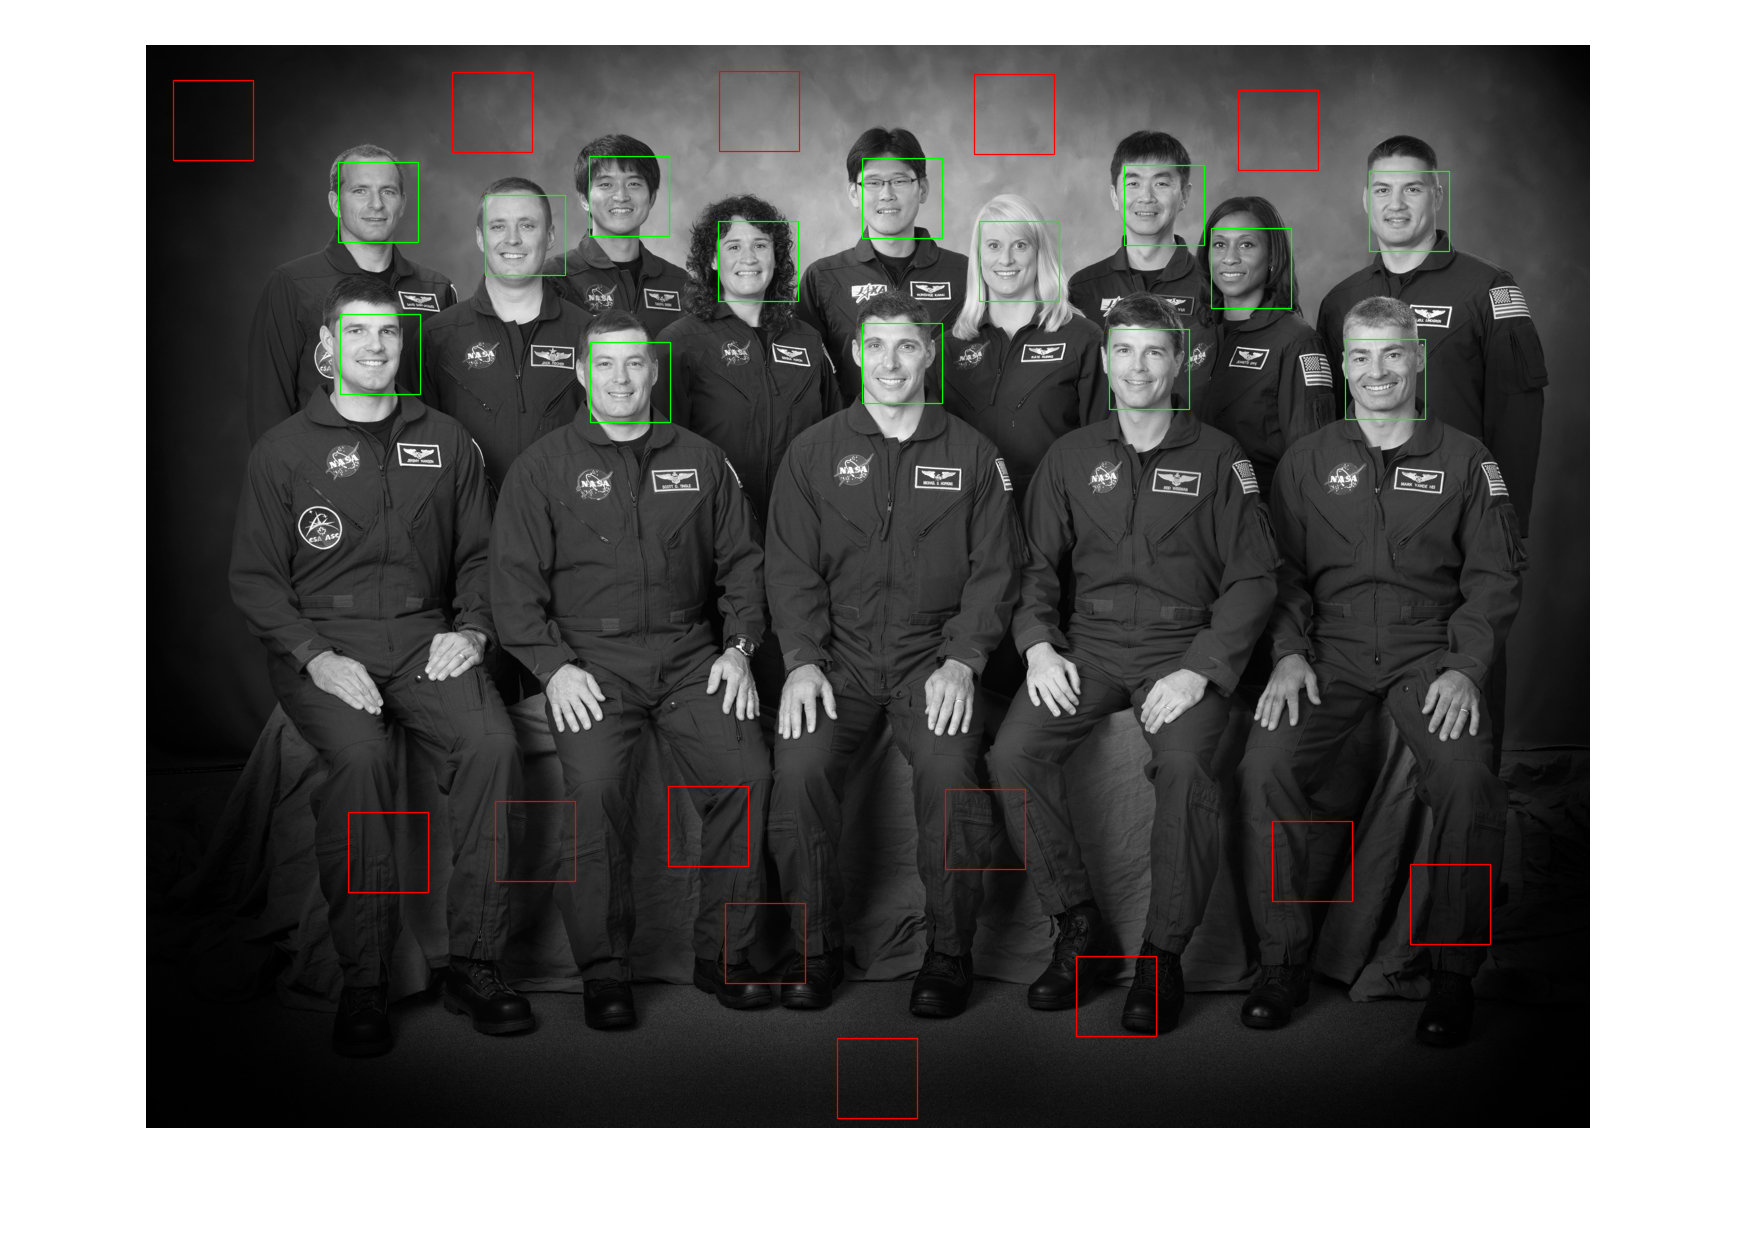

%% Visualize image with used regions
figure(4);
imshow(I);

% patches with faces
for i = 1:size(XY_FACE,1)
    PATCH = [XY_FACE(i,:) L L];
    Rectangle = [PATCH(1) PATCH(2); PATCH(1)+PATCH(3) PATCH(2); PATCH(1)+PATCH(3) PATCH(2)+PATCH(4); PATCH(1)  PATCH(2)+PATCH(4); PATCH(1) PATCH(2)];
    hold on;
    plot (Rectangle(:,1), Rectangle(:,2), 'g');
    hold off;
end

% patches without faces
for i = 1:size(XY_NON_FACE,1)
    PATCH = [XY_NON_FACE(i,:) L L];
    Rectangle = [PATCH(1) PATCH(2); PATCH(1)+PATCH(3) PATCH(2); PATCH(1)+PATCH(3) PATCH(2)+PATCH(4); PATCH(1)  PATCH(2)+PATCH(4); PATCH(1) PATCH(2)];
    hold on;
    plot (Rectangle(:,1), Rectangle(:,2), 'r');
    hold off;
end

## 2.1.2 Classification in the feature space

The following code loads the test image and selects windows with faces and non faces. 

%% Define the new regions of the test image 

% Load image 'NASA2.bmp' and convert image from rgb to grayscale 
nasa2Rgb = imread('NASA2.bmp');
% imshow(nasa2Rgb)

I = rgb2gray(nasa2Rgb);
%imshow(nasa2gray)

% % Select regions with FACES and NON-FACES
% figure(), imshow(I);
% [x1, y1] = ginput();
% x1 = round(x1);
% y1 = round(y1);

% You could use ginput only once and then copy the coordinates
x1 = [96;282;447;589;716;885;1042;1175;56;223;394;524;667;797;937;1074;1265;121;350;572;777;1022;1270];
y1 = [155;156;100;106;117;117;126;117;264;228;197;250;242;221;249;210;193;363;360;373;345;337;343];
%x1_nonface = [173;336;523;799;1107;164;346;541;765;1006;168;349;614;901;1148];
%y1_nonface = [18;23;15;18;16;760;768;766;770;755;921;921;898;890;895];

% % Difficult non faces samples
x1_nonface = [40;193;816;1282;119;561;680;903;1215];
y1_nonface = [29;125;22;34;610;506;703;529;874];

% (X,Y) coordinates of the top-left corner of windows with face
% XY_TEST = [x1 y1];
XY_TEST = [[x1;x1_nonface] [y1;y1_nonface]];

The F1 and F2 features of the selected windows are computed. 

%% Compute features for these new regions
% Compute the Integral Image
S = cumsum(cumsum(double(I),2));

% Initialize the feature matrix for faces
FEAT_TEST = [];

for i = 1:size(XY_TEST,1)
    
    % current top-left corner coordinates
    x = XY_TEST(i,1);
    y = XY_TEST(i,2);
    
    % compute area of regions A and B for the first feature
    % HERE WE USE INTEGRAL IMAGE!
    area_A = S(y+d1+h1,x+d2+w1) - S(y+d1+1,x+d2+w1) - (S(y+d1+h1,x+d2+1) - S(y+d1+1,x+d2+1));
    area_B = S(y+2*h1+d1,x+w1+d2) - S(y+d1+h1+1,x+d2+w1) - (S(y+d1+2*h1,x+d2+1)-S(y+d1+h1+1,x+d2+1));
    
    % compute area of regions C, D and E for the second feature
    % HERE WE USE INTEGRAL IMAGE!
    % >> code to compute the area of regions C and E <<
    area_C = S(y+d3+h2,x+d4+w2) -       S(y+d3+h2,x+d4) -       S(y+d3,x+d4+w2) +       S(y+d3,x+d4);
    area_D = S(y+d3+h2,x+d4+w2+w3) -    S(y+d3+h2,x+d4+w2) -    S(y+d3,x+d4+w2+w3) +    S(y+d3,x+d4+w2); 
    area_E = S(y+d3+h2,x+d4+w2+w3+w2) - S(y+d3+h2,x+d4+w2+w3) - S(y+d3,x+d4+w2+w3+w2) + S(y+d3,x+d4+w2+w3);

    % compute features value
    F1 = area_B - area_A;
    F2 = area_D - (area_C + area_E);

    % cumulate the computed values
    FEAT_TEST = [FEAT_TEST; [F1 F2]];
    
end

A *k*-nearest neighbor classifier is fit using the previous picture as a training set.

%% Train a k-nn classifier and test the new windows
features_train = [FEAT_FACE; FEAT_NON_FACE];
Group = [repmat(1, length(FEAT_FACE), 1); repmat(2, length(FEAT_NON_FACE), 1)];
% Call the function knnclassify
Mdl = fitcknn(features_train, Group, 'NumNeighbors', 2, 'Standardize', 1);

The model is then used to predict or identify the faces in the second image. 

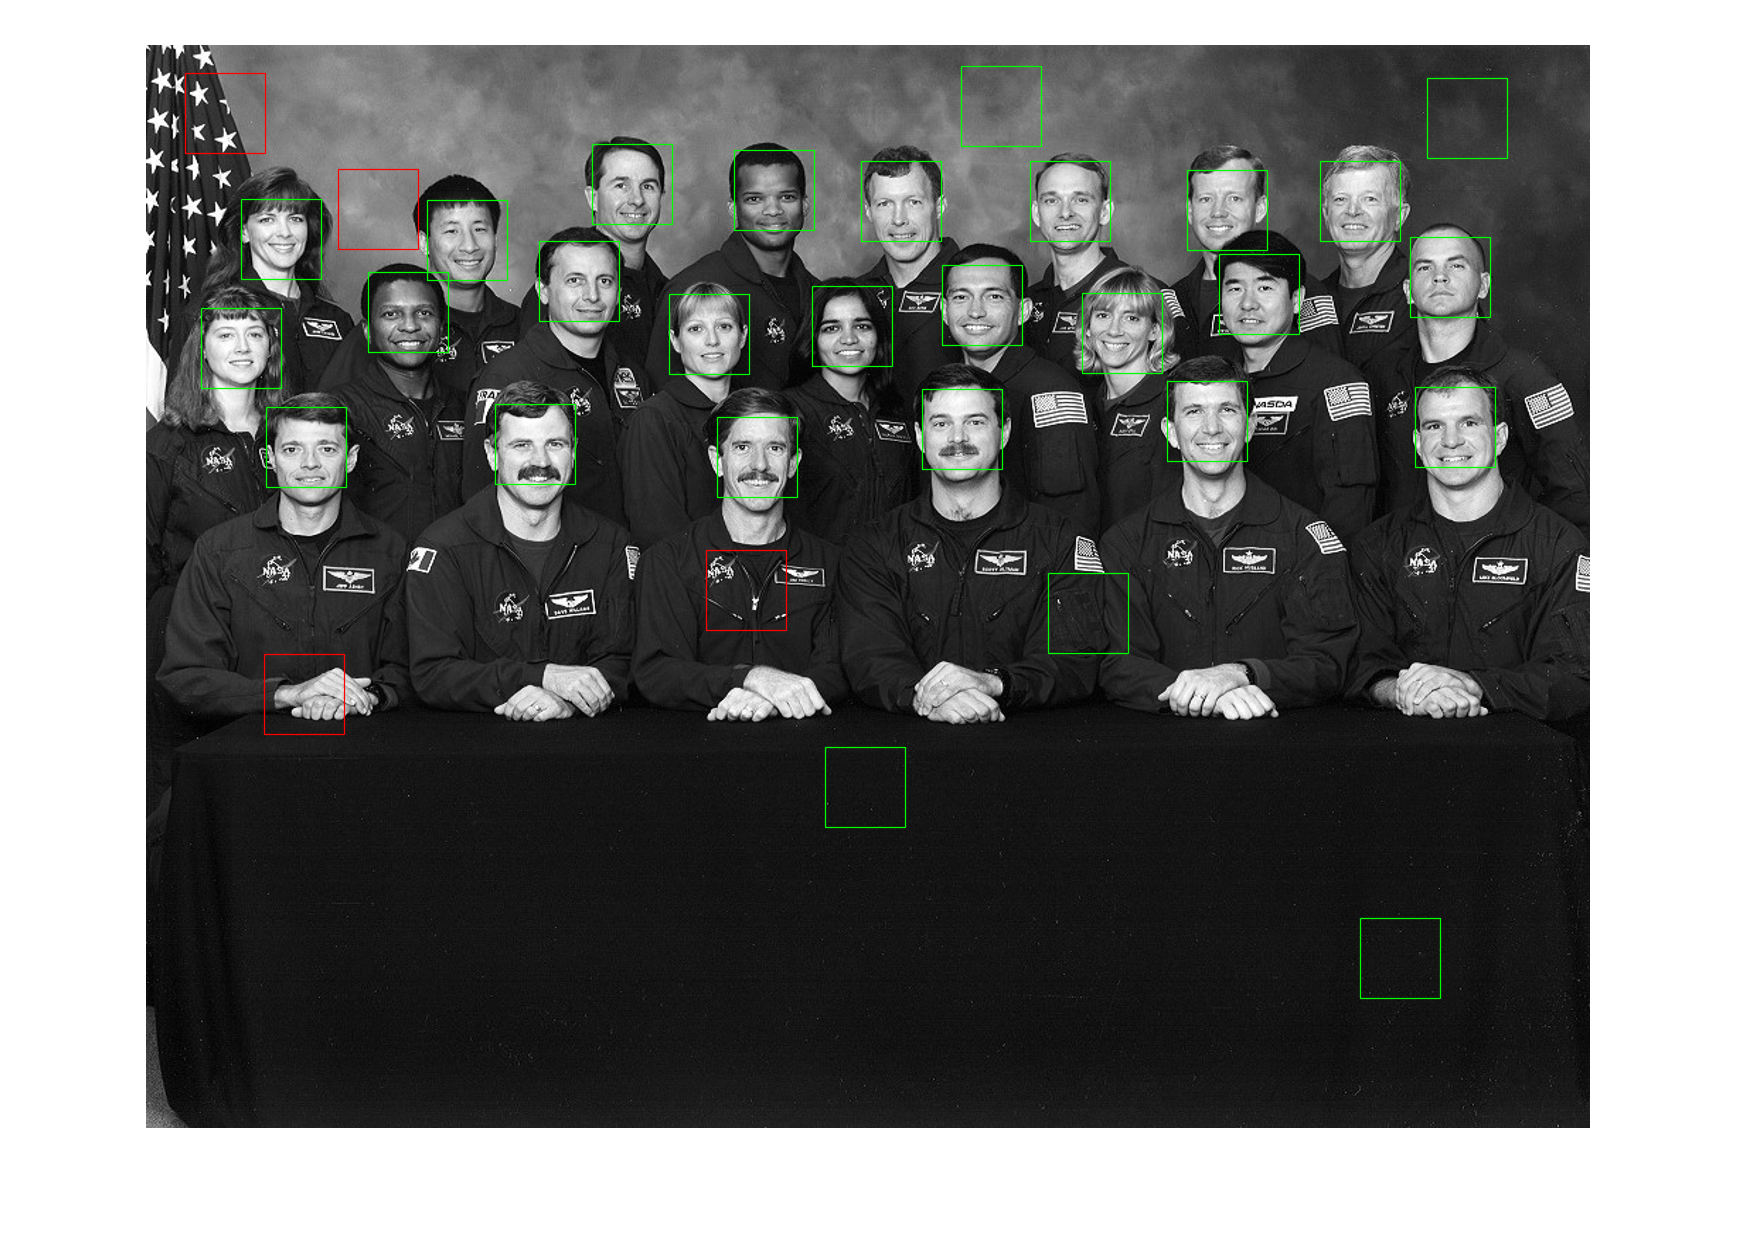

%% Visualize classification results in the test image

% Visualize image 'NASA2.bmp' with used regions
figure();
imshow(I);
XY_PREDICTED_CLASS = predict(Mdl,FEAT_TEST);
XY_CLASS = [repmat(1, length(x1), 1); repmat(2, length(x1_nonface), 1)];
% patches with faces
for i = 1:size(XY_TEST,1)
    PATCH = [XY_TEST(i,:) L L];
    Rectangle = [PATCH(1) PATCH(2); PATCH(1)+PATCH(3) PATCH(2); PATCH(1)+PATCH(3) PATCH(2)+PATCH(4); PATCH(1)  PATCH(2)+PATCH(4); PATCH(1) PATCH(2)];
    hold on;
    if(XY_PREDICTED_CLASS(i) == XY_CLASS(i))
        PATCH_COLOR = 'g';
    else
        PATCH_COLOR = 'r';
    end
    plot (Rectangle(:,1), Rectangle(:,2), PATCH_COLOR);
    hold off;
end

**Question 2: **Is the result good enough? Explain your response.

Yes, the result is good but it can be improved. The previous figure shows the correctly classified windows in green and the wrong ones in red. 32 windows were used, and only 4 were missclassified. The good news is that the 23 faces were correctly identified with the expense of 4 false positives. However, some of the non faces windows were hard to identify as the training set did not contain any sample containing hands, jackets or the flag. Non face windows with dark colours were correctly identified as negative. 

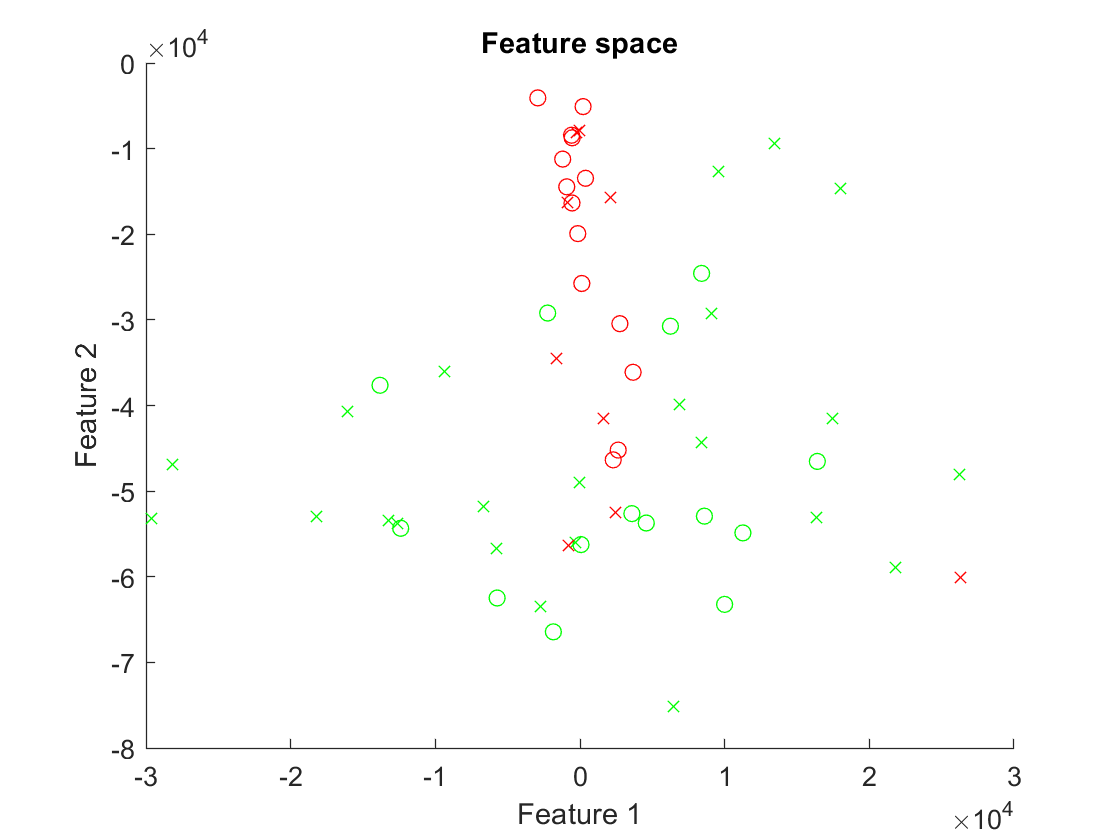

% First, visualize the training samples:
figure();
hold on
scatter(FEAT_FACE(:,1),FEAT_FACE(:,2),'g');
scatter(FEAT_NON_FACE(:,1),FEAT_NON_FACE(:,2),'r');
scatter(FEAT_TEST(XY_CLASS==1,1),FEAT_TEST(XY_CLASS==1,2),'g','x');
scatter(FEAT_TEST(XY_CLASS==2,1),FEAT_TEST(XY_CLASS==2,2),'r','x');
xlabel('Feature 1');
ylabel('Feature 2');
title('Feature space');

**Question 3: **What do you infer from the figure? Explain your response. 

The training set is marked with circles while the test set is marked with crosses. The red color representents non face windows while the greed are windows containing faces. 

The pattern of the test set is quite similar to the one of the training set. However, the test has a more variability. For example, some faces in the test set has high values of Feature 2 (around -1e4), similar to windows without faces. However, their Feature 1 values are higher than the average for non face windows.There are also some outliers as the red cross on the far right which is the window containing the hands. This particular sample was selected in order to put the model in trouble but it can be solved by training the model with more difficult samples.